# Performing Group Calculations

In this video, we will perform group calculations on blue whale data.

load cleanWhaleData.mat
whales;

whaleSummary = groupsummary(whales,"ID","range","latitude");
whaleSummary = sortrows(whaleSummary, "range_latitude", "descend")

whaleSummary = 140×3 table
           ID           GroupCount    range_latitude
    ________________    __________    ______________

    2008CA-Bmu-04176       259            34.652    
    2007CA-Bmu-01385       264            34.495    
    2005CA-Bmu-10821       276            33.208    
    2000CA-Bmu-01386       186            31.687    
    2000CA-Bmu-01390       126             30.58    
    2004CA-Bmu-04175       177            29.387    
    2005CA-Bmu-01390       260            28.747    
    2005CA-Bmu-10829       309            28.647    
    2000CA-Bmu-10828        20            28.432    
    2006CA-Bmu-02083       329            27.998    
    1998CA-Bmu-10823       226            27.936    
    1999CA-Bmu-04172       166            27.396    
    2000CA-Bmu-10832       265            26.931    
    2007CA-Bmu-23043       194            25.964    
    2007CA-Bmu-05801  

topID = whaleSummary.ID(1);

rowsToKeep = whales.ID == topID;
topWhale = whales(rowsToKeep, :)

topWhale = 259×8 table
           ID                  timestamp           longitude    latitude    sensorQuality    sensorMeasurements        sensorType         markedOutliers
    ________________    _______________________    _________    ________    _____________    __________________    ___________________    ______________

    2008CA-Bmu-04176    2008-07-28 00:40:25.000     -120.04      34.134           0                   5            argos-doppler-shift          ""      
    2008CA-Bmu-04176    2008-07-28 21:24:11.000     -120.61      34.115           0                   4            argos-doppler-shift          ""      
    2008CA-Bmu-04176    2008-07-29 21:11:49.000     -119.15      33.277           A         

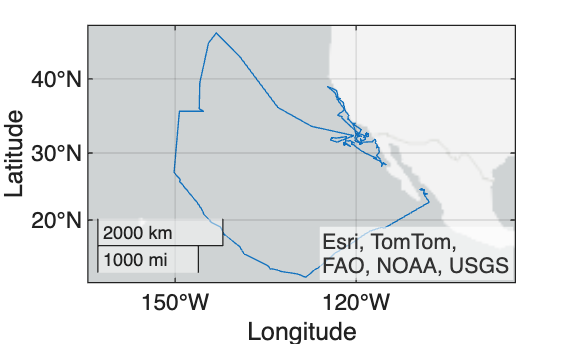


geoplot(topWhale.latitude, topWhale.longitude)